Integration five Paired-Tag datasets with JSNMF to correct batch effect

Here, JSNMF is generalizable to integrate multiple single-cell multi-omics experiments and single-cell experiments with more than two molecular modalities profiled in the same cell. In the first example, we extended JSNMF to integrate all five Paired-Tag datasets (RNA + H3K27me3, RNA + H3K4me3, RNA + H3K9me3, RNA + H3K27ac and RNA + H3K4me1) simultaneously. There are six modalities in total and the modality of RNA is shared in the five single-cell experiments. 

addpath('../others')
addpath(genpath('../data'))
addpath('../codes')
addpath('../external')

Load Paired-Tag dataset: H3K4me3

load('h3k4me3_5k_10k.mat')
num_clu1 = length(unique(label));
X12 = X2; label1 = label; rna1 = genes; barcode1 = share_bd;
clear X1 X2 genes label share_bd feas label_h3k4me1

Load Paired-Tag dataset: H3K27ac

load('h3k27ac_5k_10k.mat')
num_clu2 = length(unique(label));
X23 = X2; label2 = label; rna2 = genes; barcode2 = share_bd;
clear X1 X2 genes label share_bd feas label_h3k27me3

Load Paired-Tag dataset: H3K27me3

load('h3k27me3_5k_10k.mat')
num_clu3 = length(unique(label));
X34 = X2; label3 = label; rna3 = genes; barcode3 = share_bd;
clear X1 X2 genes label share_bd feas label_h3k27me3

Load Paired-Tag dataset: H3K9me3

load('h3k9me3_5k_10k.mat')
num_clu4 = length(unique(label));
X45 = X2; label4 = label; rna4 = genes; barcode4= share_bd;
clear X1 X2 genes label share_bd feas label_h3k4me1

Load Paired-Tag dataset: H3K4me1

load('h3k4me1_5k_10k.mat')
num_clu5 = length(unique(label));
X56 = X2; label5 = label; rna5 = genes; barcode5= share_bd;
clear X1 X2 genes label share_bd feas label_h3k4me1

Get intersect and diffsect for five paried-Tag datasets

share_gene = intersectvecs(rna1,rna2,rna3,rna4,rna5);
diffsets_tot = getdiffsets(share_gene,rna1,rna2,rna3,rna4,rna5);
same_genes = [share_gene;diffsets_tot]; same_genes = string(same_genes);

Preparing for computing RAGI

load('paired_tag_original.mat','RNA','barcodes')
load('pari-tag_processRNA_full.mat')
load('pari-tag_genes.mat')

[~,~,ix1] = intersect(barcode1,barcodes,'stable'); %h3k4me3
[~,~,ix2] = intersect(barcode2,barcodes,'stable'); %h3k27ac
[~,~,ix3] = intersect(barcode3,barcodes,'stable'); %h3k27me3
[~,~,ix4] = intersect(barcode4,barcodes,'stable'); %h3k9me3
[~,~,ix5] = intersect(barcode5,barcodes,'stable'); %h3k4me1
[~,id,~] = intersect(genes,same_genes);

X11 = RNA(id,ix1); X21 = RNA(id,ix2); X31 = RNA(id,ix3); X41 = RNA(id,ix4); X51 = RNA(id,ix5); 

marker_genes = ["Dnah12"; "Cfap299";'Flt1'; 'Slco1a4'; 'Inpp5d'; 'Hexb'; 'Slc1a3'; 'Atp1a2'; 'Slc1a2'; 'Gpc5'; ...
    'Prr5l'; 'Plp1'; 'Rnf220'; 'Lhfpl3'; 'Cacng4'; 'Erbb4'; 'Kcnc2'; 'Reln'; 'Grin3a'; 'Adarb2'; 'Fam19a2'; ...
    'Ahcyl2'; 'Gm32647'; 'Shisa6'; 'Epha6'; 'Galnt14'; 'Hs3st4'; 'Tshz2'; 'Fam19a1'; 'Il1rapl2'; 'Cdh12'; 'Rgs6';...
    'Lingo2'; 'Prr16'; 'Zfp804b'; 'Pex5l'; 'Gm26883'; 'Cdh18'; 'Gm28928'; 'Galntl6'; 'Spag16'; 'Cfap43'; 'Wdr49';...
    'Ebf1'; 'Mecom'; 'Ptprb'; 'Tgfbr1'; 'Zfhx3'; 'Apbb1ip'; 'Gpc5'; 'Plpp3'; 'Slc1a2'; 'Igsf8'; 'St18'; 'Mog'; 'Mag';...
    'St18'; 'Mbp'; 'Vcan'; 'Tnr'; '6030443J06Rik'; 'Nxph1'; '6330411D24Rik'; 'Kcnmb2'; 'Grip1'; 'Gm45341'; 'Gm45455';...
    'Grip1'; 'Trpm3'; 'Rfx3'; 'Dgkh'; 'Hs3st4'; 'Ryr3'; 'Hs6st3'; 'Gm2164'; 'Grik4'; 'Cpne7'; 'Gm2164'; 'Ryr3';...
    'Hs6st3'; 'Sdk1'; 'Foxp2'; 'Garnl3hrm2'; 'Grm8'; 'Vwc2l'; 'Olfm3'; 'Grik1 Gm2164'; 'Gm28928'; 'Sgcz'; 'Prr16'; ...
    'Chrm3'; 'Pdzrn3'; 'Kcnq5'; 'Unc5d'; 'Car10'; 'Pcdh15'; 'Nrg1']; 
marker_genes = unique(marker_genes);

load('data/housekeeping_genes.mat')
housekeeping_genes = hp_genes;

load('rna_RAGI/h3k4me3_rna_RAGI.mat')
genes1 = genes_h3k4me3; data1 = rna_h3k4me3; 
clear genes_h3k4me3 rna_h3k4me3

load('rna_RAGI/h3k27ac_rna_RAGI.mat')
genes2 = genes_h3k27ac; data2 = rna_h3k27ac; 
clear genes_h3k27ac rna_h3k27ac

load('rna_RAGI/h3k27me3_rna_RAGI.mat')
genes3 = genes_h3k27me3; data3 = rna_h3k27me3;
clear genes_h3k27me3 rna_h3k27me3

load('rna_RAGI/h3k9me3_rna_RAGI.mat')
genes4 = genes_h3k9me3; data4 = rna_h3k9me3;
clear genes_h3k9me3 rna_h3k9me3

load('rna_RAGI/h3k4me1_rna_RAGI.mat')
genes5 = genes_h3k4me1; data5 = rna_h3k4me1;
clear genes_h3k4me1 rna_h3k4me1

[~,~,ind11] = intersect(marker_genes,genes1,'stable');
[~,~,ind12] = intersect(housekeeping_genes,genes1,'stable');

[~,~,ind21] = intersect(marker_genes,genes2,'stable');
[~,~,ind23] = intersect(housekeeping_genes,genes2,'stable');

[~,~,ind31] = intersect(marker_genes,genes3,'stable');
[~,~,ind34] = intersect(housekeeping_genes,genes3,'stable');

[~,~,ind41] = intersect(marker_genes,genes4,'stable');
[~,~,ind45] = intersect(housekeeping_genes,genes4,'stable');

[~,~,ind51] = intersect(marker_genes,genes5,'stable');
[~,~,ind56] = intersect(housekeeping_genes,genes5,'stable');

clear RNA barcodes barcode1 barcode2 genes genes1 genes2 rna1 rna2 rna3 rna 4 rna5 share_gene same_genes 


Parameter seletion 

[alpha, gamma, Inits] = parameter_selection_batcheffect_pair5(X11, X12, X21, X23,X31,X34,X41, X45,X51,X56, num_clu1,num_clu2,num_clu3,num_clu3,num_clu5);

Implement batch effect correction with the variant of JSNMF

% start time
tic
[~,~,~,~,~,~,H11,~,H21,~,H31,~,H41,~,H51,~,S1,S2,S3,S4,S5,iter,objs] = jsnmf_batch_correct_pari5(X11,X12,X21,X23,X31,X34,X41, X45,X51,X56,alpha,gamma,Inits);

iteration starts!
number of iteration:10  obj:10645811.8075
number of iteration:20  obj:10422117.8994
number of iteration:30  obj:10300338.5605
number of iteration:40  obj:10234816.4371
number of iteration:50  obj:10198952.4839
number of iteration:60  obj:10179893.5396
number of iteration:70  obj:10168478.4898
number of iteration:80  obj:10160182.0822
number of iteration:90  obj:10153529.8587
number of iteration:100  obj:10147794.1403
number of iteration:110  obj:10142860.9044
number of iteration:120  obj:10138816.174
number of iteration:130  obj:10135333.0555
number of iteration:140  obj:10132362.9003
number of iteration:150  obj:10129690.4499
number of iteration:160  obj:10126747.1141
number of iteration:170  obj:10123487.2399
number of iteration:180  obj:10120414.3462
number of iteration:190  obj:10117304.7039
number of iteration:200  obj:10115461.9173
number of iteration:210  obj:10114093.4838
number of iteration:220  obj:10112650.295
number of iteration:230  obj:10111343.4111
conv

disp('JSNMF runtime:');

JSNMF runtime:


toc

历时 3427.520362 秒。



% clutering on each Paried-Tag data
% H3k4me3
A1 = Wtrim(S1,50); % KNN on S

% implement louvain clustering
[clust,~,~] = getNCluster(A1,num_clu1,0,3,20); 
[ac1, nmi_value1, ~] = CalcMetrics(label1, clust);

ac: 0.8349	443/2684	nmi:0.8236	


[~, ~, difgini1] = RAGI(data1,ind11,ind12,clust);

ave_marker_gene: 0.4274	ave_hk_gini:0.2042	diff_gini:0.2232	



% H3k27ac
A2 = Wtrim(S2,50); 
[clust,~,~] = getNCluster(A2,num_clu2,0,3,20); 
[ac2, nmi_value2, ~] = CalcMetrics(label2, clust);

ac: 0.8074	1399/7262	nmi:0.8355	


[~, ~, difgini2] = RAGI(data2,ind21,ind23,clust);

ave_marker_gene: 0.4057	ave_hk_gini:0.1240	diff_gini:0.2817	



% H3k27me3
A3 = Wtrim(S3,50); 
[clust,~,~] = getNCluster(A3,num_clu3,0,3,20); 
[ac3, nmi_value3, ~] = CalcMetrics(label3, clust);

ac: 0.7711	986/4307	nmi:0.7904	


[~, ~, difgini3] = RAGI(data3,ind31,ind34,clust);

ave_marker_gene: 0.3842	ave_hk_gini:0.1404	diff_gini:0.2439	



% H3k9me3
A4 = Wtrim(S4,50); 
[clust,~,~] = getNCluster(A4,num_clu4,0,3,20); 
[ac4, nmi_value4, ~] = CalcMetrics(label4, clust);

ac: 0.8064	1583/8176	nmi:0.8543	


[~, ~, difgini4] = RAGI(data4,ind41,ind45,clust);

ave_marker_gene: 0.4316	ave_hk_gini:0.1238	diff_gini:0.3078	



% h3k4me1
A5 = Wtrim(S5,50); % KNN on S
[clust,~,~] = getNCluster(A5,num_clu5,0,3,20); 
[ac5, nmi_value5, ~] = CalcMetrics(label5, clust);

ac: 0.8208	1548/8637	nmi:0.8495	


[~, ~, difgini5] = RAGI(data5,ind51,ind56,clust);

ave_marker_gene: 0.3981	ave_hk_gini:0.1341	diff_gini:0.2640	


UMAP visualization on S1-S5 to correct batch effection

% visualization on S
addpath('../umapFileExchange/umap') % load UMAP package

addpath('../umapFileExchange/util')

Can not reach host ":80  because ":  Connection refused: connect
Can not reach host "cgworkspace.cytogenie.org:80  because ":  杩欐槸鍦ㄤ富鏈哄悕瑙ｆ瀽鏃堕�氬父鍑虹幇鐨勬殏鏃堕敊璇紝瀹冩剰鍛崇潃鏈湴鏈嶅姟鍣ㄦ病鏈変粠鏉冨▉鏈嶅姟鍣ㄤ笂鏀跺埌鍝嶅簲銆� (cgworkspace.cytogenie.org)
Can not reach host "drive.google.com:80  because ":  connect timed out
Can not reach host "54.39.2.45:80  because ":  connect timed out


Parallelizing UMAP with MATLAB's 16 assigned logical cores for nn_descent_tasks, sgd_tasks
 Running basic (ub) reduction, v2.1.3
(ub=basic, us=supervised, ubt=template, ust=supervised template)


UMAP(method=MEX, n_neighbors=12, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.68, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.341574797469203, b=1.53967627863961, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


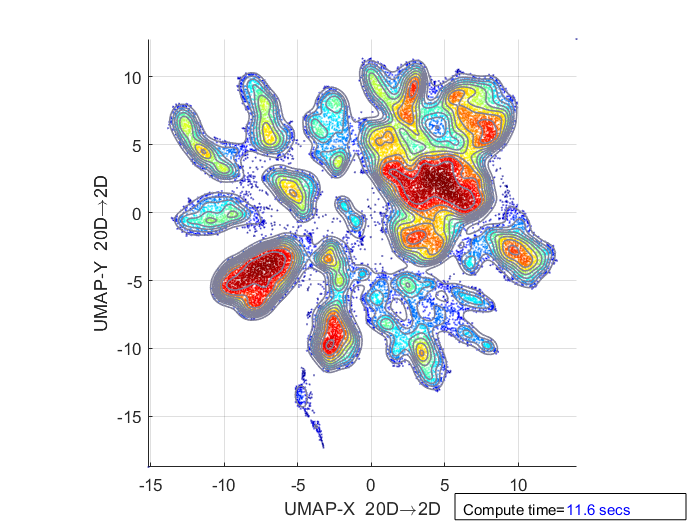

UMAP reduction finished (cost 11.7 secs)
 Finished basic (ub) reduction



load('label_name_paried_all.mat')
% label_h3k9me3 = erase(label_h3k9me3,'\');
term = '.'; 

uni_h3k4me3 = unique(label_h3k4me3);
uni_h3k27ac = unique(label_h3k27ac);
uni_h3k27me3 = unique(label_h3k27me3);
uni_h3k9me3 = unique(label_h3k9me3);
uni_h3k4me1 = unique(label_h3k4me1);

% judege whether two cell type is equal
isequal(uni_h3k4me3,uni_h3k27ac);  %1
isequal(uni_h3k4me3,uni_h3k27me3); %1
isequal(uni_h3k4me3,uni_h3k4me1);  %1

% for H3K9me3 data, there are 22 clusters. To be consistent with other
% data, 2 rare cell type is discarded

[diff_type,~] = setdiff(uni_h3k9me3,uni_h3k27ac,'stable');
id1 = find(label_h3k9me3 == diff_type(1)); 
id2 = find(label_h3k9me3 == diff_type(2));
id_tot = [id1;id2];
label_h3k9me3(id_tot,:) = []; H41(id_tot,:) = [];

% aggreate label name of all paired-tag data for visualization
label_name = [label_h3k4me3; label_h3k27ac; label_h3k27me3; label_h3k9me3; label_h3k4me1];
H = [H11; H21; H31; H41; H51];

colors = generateColors(max(length(unique(label_name))),length(unique(term)));
[reduction_jsnmf, ~, ~, ~] = run_umap(H,'min_dist',0.68,'n_neighbors',12); 

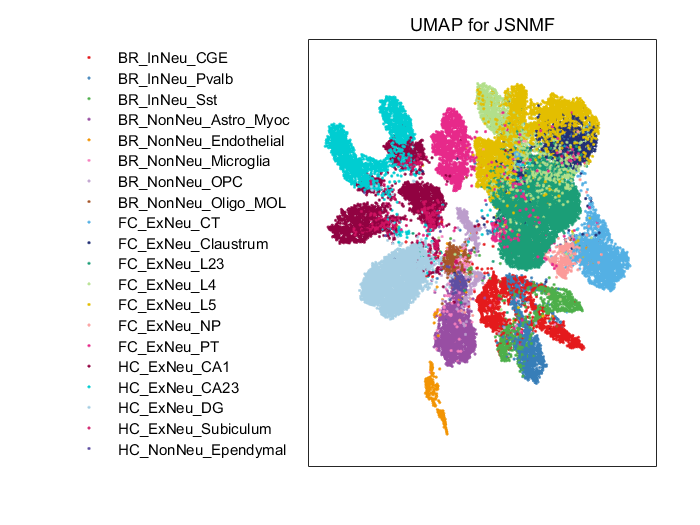


% get number of cells for each data
n1 = size(H11,1); 
n2 = size(H21,1); 
n3 = size(H31,1); 
n4 = size(H41,1);
n5 = size(H51,1);

% sort cell type on H3K4me3
[~,I_1] = sort(label_name(1:n1)); 
[B_2,I_2] = sort(label_name(n1+1:n1+n2));
k4me3_red = reduction_jsnmf(1:n1,:); 
sorted_k4me3_red = k4me3_red(I_1,:);
label_name_k4me3 = label_name(1:n1); 
label_name_k4me3 = label_name_k4me3(I_1);

% sort cell type on H3K27ac
k27ac_red = reduction_jsnmf(n1+1:n1+n2,:); 
sorted_k27ac_red = k27ac_red(I_2,:);
label_name_k27ac = label_name(n1+1:n1+n2); 
label_name_k27ac = label_name_k27ac(I_2);

a = n1+n2; b = n1+n2+n3; c = n1+n2+n3+n4; d = n1+n2+n3+n4+n5;

[~,I_3] = sort(label_name(a+1:b)); 
[~,I_4] = sort(label_name(b+1:c)); 
[~,I_5] = sort(label_name(c+1:d));

% sort cell type on H3K27me3
k27me3_red = reduction_jsnmf(a+1:b,:); 
sorted_k27me3_red = k27me3_red(I_3,:);
label_name_k27me3 = label_name(a+1:b); 
label_name_k27me3 = label_name_k27me3(I_3);

% sort cell type on H3K9me3
k9me3_red = reduction_jsnmf(b+1:c,:); 
sorted_k9me3_red = k9me3_red(I_4,:);
label_name_k9me3 = label_name(b+1:c); 
label_name_k9me3 = label_name_k9me3(I_4);

% sort cell type on H3K4me1
k4me1_red = reduction_jsnmf(c+1:d,:); 
sorted_k4me1_red = k4me1_red(I_5,:);
label_name_k4me1 = label_name(c+1:d); 
label_name_k4me1 = label_name_k4me1(I_5);

label_name_k4me3 = strrep(label_name_k4me3,'_','\_'); 
label_name_k27ac = strrep(label_name_k27ac,'_','\_');
label_name_k27me3 = strrep(label_name_k27me3,'_','\_'); 
label_name_k9me3 = strrep(label_name_k9me3,'_','\_');
label_name_k4me1 = strrep(label_name_k4me1,'_','\_');

% plot scatter figure 
gscatter(sorted_k4me3_red(:,1),sorted_k4me3_red(:,2),label_name_k4me3, colors,'.',4); 
hold on
gscatter(sorted_k27ac_red(:,1),sorted_k27ac_red(:,2),label_name_k27ac, colors, '.',4); 
hold on
gscatter(sorted_k27me3_red(:,1),sorted_k27me3_red(:,2),label_name_k27me3, colors, '.',4); 
hold on
gscatter(sorted_k9me3_red(:,1),sorted_k9me3_red(:,2),label_name_k9me3, colors,'.',4); 
hold on
gscatter(sorted_k4me1_red(:,1),sorted_k4me1_red(:,2),label_name_k4me1, colors, '.',4); 
hold on

set(gca,'xtick',[],'ytick',[]);
title('UMAP for JSNMF')
legend('Location','westoutside','Box','off','FontSize',9.5); 
legendmarkeradjust(12) 
legend('boxoff')